A = [3 2 1; 2 4 1; 3 9 2]

A =      3     2     1
     2     4     1
     3     9     2


B = A'     %求转置

B =      3     2     3
     2     4     9
     1     1     2


[D,V] = eig(A)  % 求特征值和特征向量

D =    -0.3534   -0.5691   -0.2508
   -0.4152    0.1144   -0.1181
   -0.8383    0.8143    0.9608


V =     7.7217         0         0
         0    1.1673         0
         0         0    0.1109


E = inv(A)  % 求逆矩阵

E =    -1.0000    5.0000   -2.0000
   -1.0000    3.0000   -1.0000
    6.0000  -21.0000    8.0000


F = A*E

F =     1.0000         0         0
    0.0000    1.0000         0
    0.0000         0    1.0000


三维图：

% [X,Y]=meshgrid(-2:0.1:2);
% 
% x = 0:2:6;
% y = 0:1:6;
% z = 0:3:6;
% [X,Y,Z] = meshgrid(-2,0.1,2);
% F = X.^2 + Y.^2 + Z.^2;
% surf(X,Y,Z);

[X,Y]=meshgrid(-2:0.1:2);
Z=X.^2+Y.^2

Z =     8.0000    7.6100    7.2400    6.8900    6.5600    6.2500    5.9600    5.6900    5.4400    5.2100    5.0000    4.8100    4.6400    4.4900    4.3600    4.2500    4.1600    4.0900    4.0400    4.0100    4.0000    4.0100    4.0400    4.0900    4.1600    4.2500    4.3600    4.4900    4.6400    4.8100    5.0000    5.2100    5.4400    5.6900    5.9600    6.2500    6.5600    6.8900    7.2400    7.6100    8.0000
    7.6100    7.2200    6.8500    6.5000    6.1700    5.8600    5.5700    5.3000    5.0500    4.8200    4.6100    4.4200    4.2500    4.1000    3.9700    3.8600    3.7700    3.7000    3.6500    3.6200    3.6100    3.6200    3.6500    3.7000    3.7700    3.8600    3.9700    4.1000    4.2500    4.4200    4.6100    4.8200    5.0500    5.3000    5.5700    5.8600    6.1700    6.5000    6.8500    7.2200    7.6100
    7.2400    6.8500    6.4800    6.1300    5.8000    5.4900    5.2000    4.9300    4.6800    4.4500    4.2400    4.0500    3.8800    3.7300    3.6000    3.4900    3.4000    

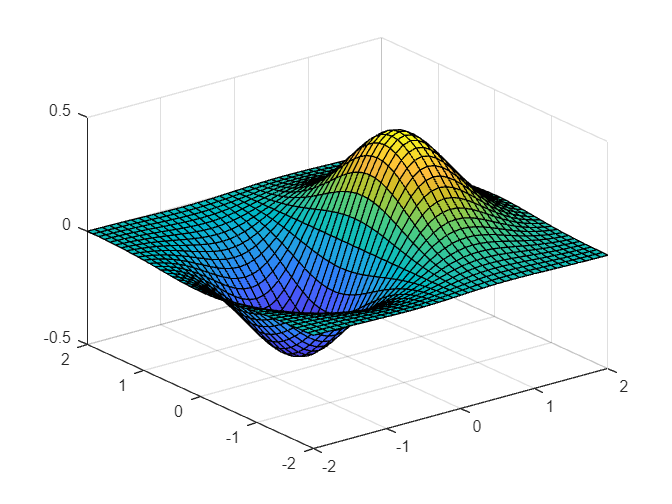

Z=X.*exp(-X.^2-Y.^2);     %-X.^2-Y.^2 负号在这个式子中的含义是什么？
surf(X,Y,Z);

条形图 

**bar函数绘制条形图 barh函数绘制水平条形图（x,y对调）**

t=-2:0.1:2

t =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


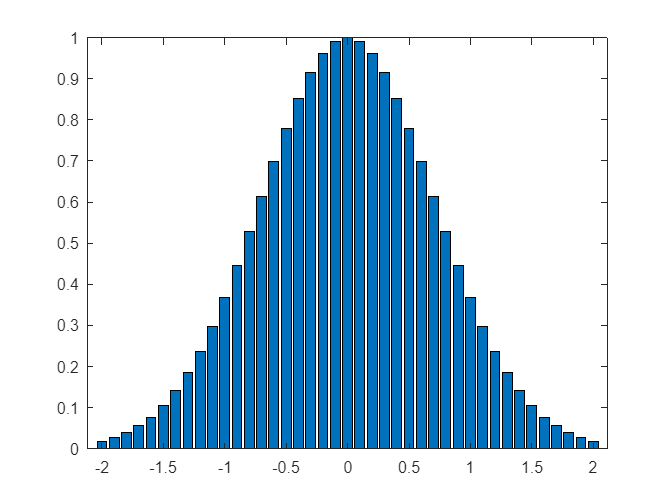

p=exp(-t.*t);
bar(t,p)

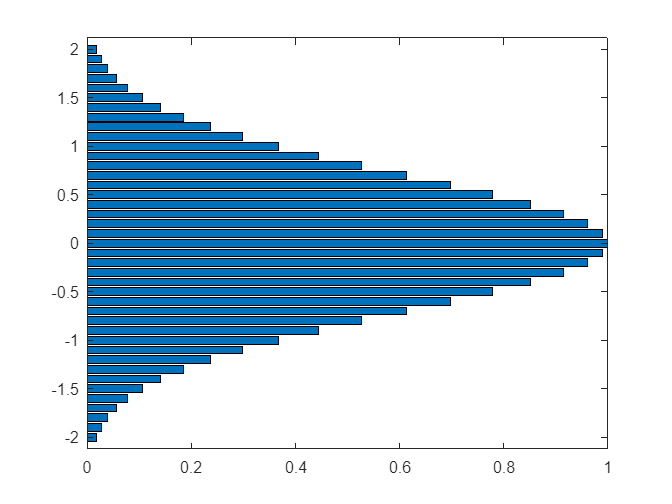

barh(t,p)

极坐标图

polarplot函数用于绘制极坐标图

theta =(-2:0.01:2*pi)

theta =    -2.0000   -1.9900   -1.9800   -1.9700   -1.9600   -1.9500   -1.9400   -1.9300   -1.9200   -1.9100   -1.9000   -1.8900   -1.8800   -1.8700   -1.8600   -1.8500   -1.8400   -1.8300   -1.8200   -1.8100   -1.8000   -1.7900   -1.7800   -1.7700   -1.7600   -1.7500   -1.7400   -1.7300   -1.7200   -1.7100   -1.7000   -1.6900   -1.6800   -1.6700   -1.6600   -1.6500   -1.6400   -1.6300   -1.6200   -1.6100   -1.6000   -1.5900   -1.5800   -1.5700   -1.5600   -1.5500   -1.5400   -1.5300   -1.5200   -1.5100


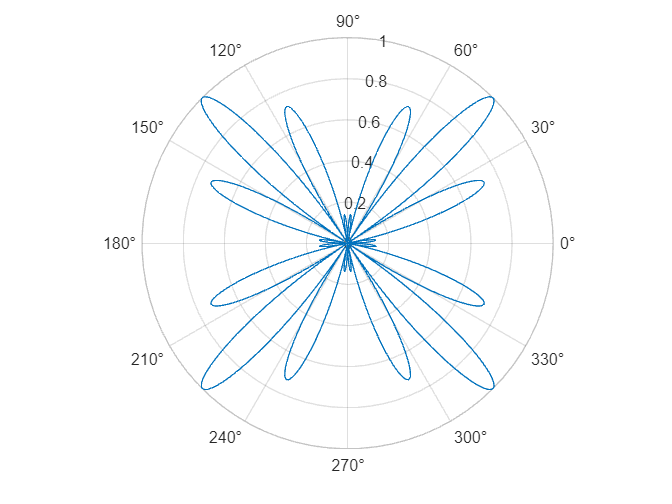

radi = abs(sin(2*theta).*cos(8*theta));   %abs函数：求绝对值
polarplot(theta,radi);